defaultDir = 'M:\Projects and Analysis\Papers\P2ry1'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd('Figure 6 - SGNs');


%%Analysis of the entire MRS2500 trace
datadir = '.\Data\WT_MRS2500\'

datadir = '.\Data\WT_MRS2500\'

opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500\15719003.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1750.6 s ~ 29 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 534 MB


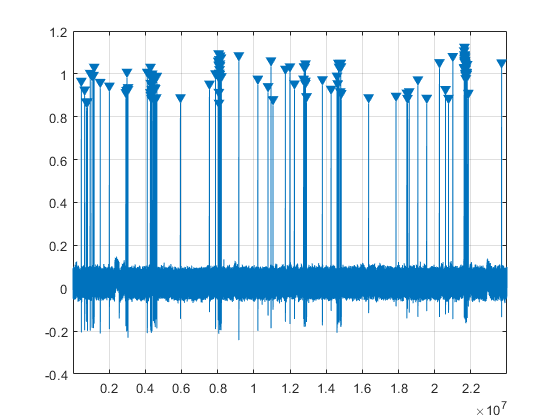

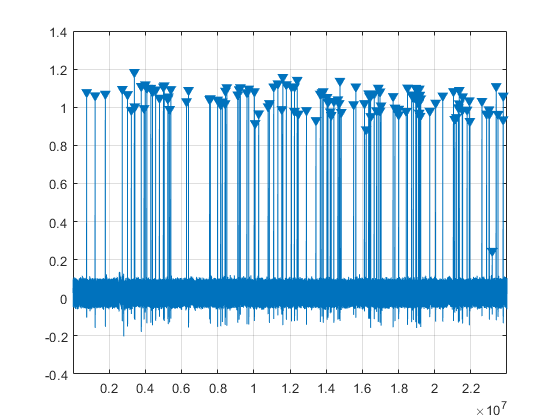

opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500\15723000.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1677.6 s ~ 28 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 512 MB


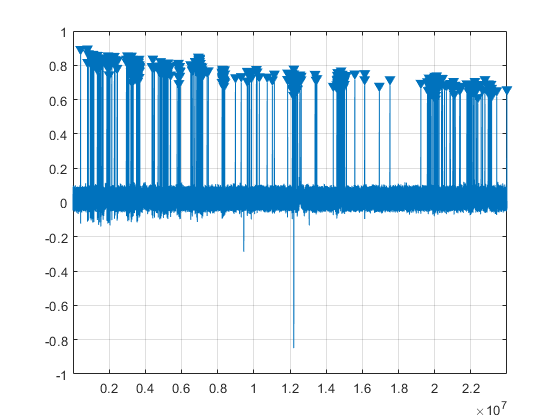

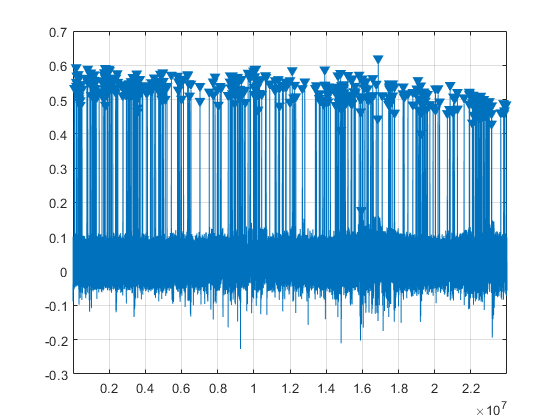

opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500\15723002.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1802.5 s ~ 30 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 550 MB


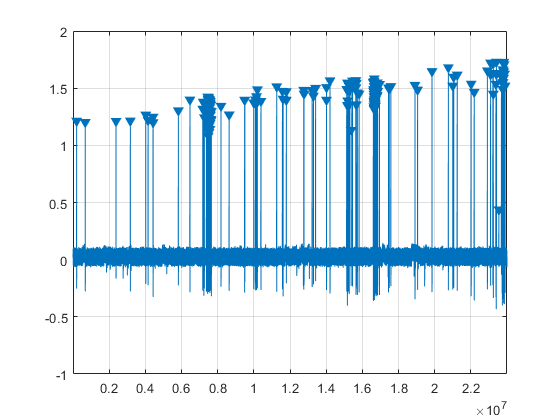

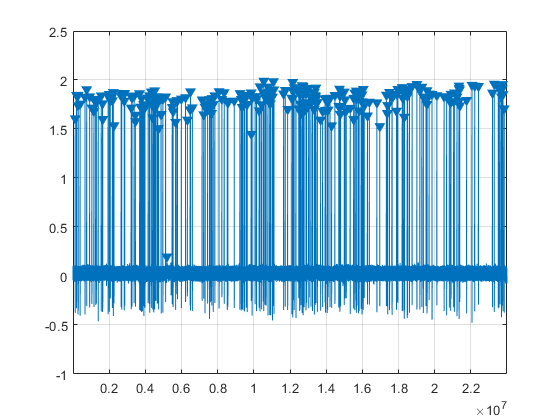

opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500\15723003.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1884.5 s ~ 31 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 575 MB


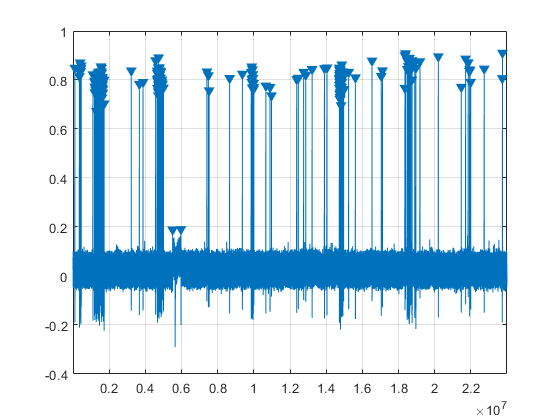

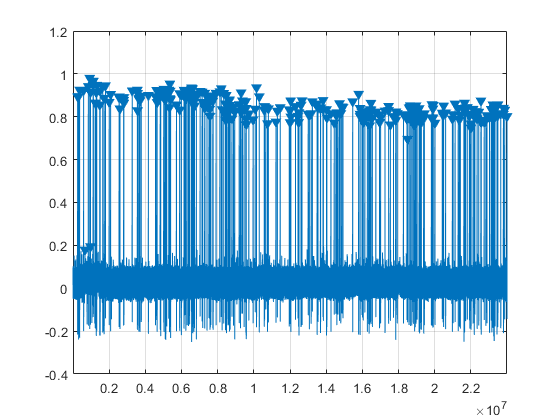

opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500\15723006.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 2010.4 s ~ 34 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 614 MB


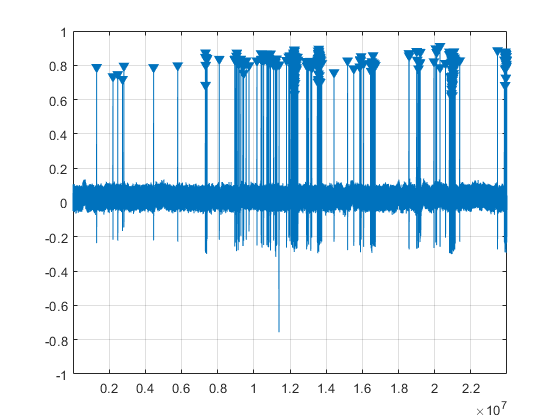

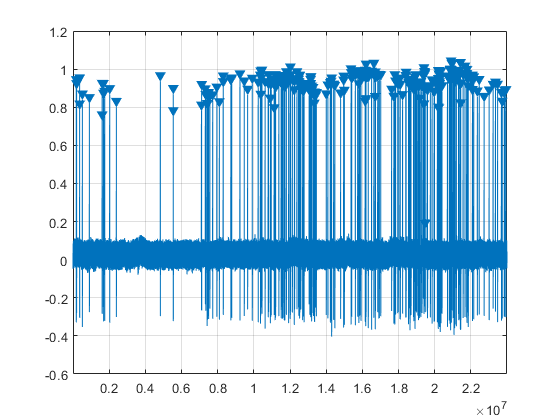

opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500\15724007.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1930.4 s ~ 32 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 589 MB


opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS2500\15725007.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1808.8 s ~ 30 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 552 MB


filelist = loadFileList([datadir '*.abf']);

%%all spikes
% for i = 1:size(filelist,1)
%     [d,time] = loadPclampData(filelist{i});
%     spikes = findSpikes(d, time*1000, [1 28*60], .3);
%     [~,name,~] = fileparts(filelist{i});
%     save([datadir name '_allSpikes.mat'],'spikes','-mat')
% end

%measure between 0 and 10 minutes for baseline, 15-25 minutes for MRS
 for i = 1:size(filelist,1)
     [d,time] = loadPclampData(filelist{i});
    spikes = findSpikes(d, time*1000, [0 600], .3);
    [~,name,~] = fileparts(filelist{i});
     save([datadir name '_spikes.mat'],'spikes','-mat')
     
     spikes = findSpikes(d, time*1000, [900 1500], .3);
    [~,name,~] = fileparts(filelist{i});
     save([datadir name '_MRSspikes.mat'],'spikes','-mat')
     
 end

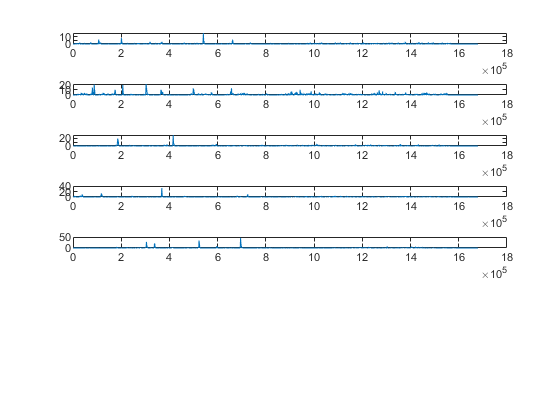

spike_paths = loadFileList('.\Data\WT_MRS2500\*allSpikes.mat');
ISIs = [];
convolved = [];
figure;
for i = 1:5
    load(spike_paths{i});
    newTimes = round(spikes.times);
    spikesBin = zeros(size(0:.001:28*60-1));
    spikesBin(newTimes) = 1;
    convData = conv(spikesBin',ones(1000,1),'same');
    convolved(i,:) = decimate(convData,1000);
    subplot(size(spike_paths,1),1,i)
        plot(conv(spikesBin',ones(1000,1),'same'))
    %subplot(size(WT_spike_paths,1),2,i);
   %     plot(spikes.ISI,'.'); set(gca, 'YScale', 'log'); ylim([10^0 10^5]);
   %  subplot(size(WT_spike_paths,1),2,i+size(WT_spike_paths,1));
    %    histogram(spikes.times*1000, 600/10); ylim([0 100]);
    ISIs = [ISIs; spikes.ISI];
end

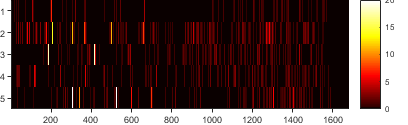


figure; imagesc(convolved); colormap htmp; caxis([0 20]);
colorbar;
figQuality(gcf,gca,[4.25 1.3]);
export_fig(['.\EPS Panels\MRS2500_heatmap.pdf'])
print(['.\EPS Panels\MRS2500_heatmap.pdf'])

burst_thr = 1000;
streakForBurst = 10;

WT_spike_paths = loadFileList('.\Data\WT_MRS2500\*spikes.mat');

for i = 1:size(WT_spike_paths)
    load(WT_spike_paths{i})
    bursts = findBursts(spikes.ISI, burst_thr, spikes.times, streakForBurst)
    save(WT_spike_paths{i},'spikes','bursts','-mat');
end

bursts = struct with fields:
    streakForBurst: 10
         numBursts: 0
        burstsLocs: [0×2 double]
     spikePerBurst: [0×1 double]
         durations: [0×1 double]
          burstThr: 1000


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 3
        burstsLocs: [3×2 double]
     spikePerBurst: [3×1 double]
         durations: [3×1 double]
          burstThr: 1000


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 3
        burstsLocs: [3×2 double]
     spikePerBurst: [3×1 double]
         durations: [3×1 double]
          burstThr: 1000


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 3
        burstsLocs: [3×2 double]
     spikePerBurst: [3×1 double]
         durations: [3×1 double]
          burstThr: 1000


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 11
        burstsLocs: [11×2 double]
     spikePerBurst: [11×1 double]
         durations: [11×1 double]
          burstThr: 1000


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 7
        burstsLocs: [7×2 double]
     spikePerBurst: [7×1 double]
         durations: [7×1 double]
          burstThr: 1000


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 1
        burstsLocs: [1.1021e+05 1.1364e+05]
     spikePerBurst: 11
         durations: 3.4284e+03
          burstThr: 1000


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 4
        burstsLocs: [4×2 double]
     spikePerBurst: [4×1 double]
         durations: [4×1 double]
          burstThr: 1000


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 2
        burstsLocs: [2×2 double]
     spikePerBurst: [2×1 double]
         durations: [2×1 double]
          burstThr: 1000


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 0
        burstsLocs: [0×2 double]
     spikePerBurst: [0×1 double]
         durations: [0×1 double]
          burstThr: 1000


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 6
        burstsLocs: [6×2 double]
     spikePerBurst: [6×1 double]
         durations: [6×1 double]
          burstThr: 1000


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 5
        burstsLocs: [5×2 double]
     spikePerBurst: [5×1 double]
         durations: [5×1 double]
          burstThr: 1000


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 1
        burstsLocs: [5.0374e+05 5.0852e+05]
     spikePerBurst: 15
         durations: 4.7816e+03
          burstThr: 1000


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 6
        burstsLocs: [6×2 double]
     spikePerBurst: [6×1 double]
         durations: [6×1 double]
          burstThr: 1000


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 3
        burstsLocs: [3×2 double]
     spikePerBurst: [3×1 double]
         durations: [3×1 double]
          burstThr: 1000


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 0
        burstsLocs: [0×2 double]
     spikePerBurst: [0×1 double]
         durations: [0×1 double]
          burstThr: 1000


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 5
        burstsLocs: [5×2 double]
     spikePerBurst: [5×1 double]
         durations: [5×1 double]
          burstThr: 1000


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 4
        burstsLocs: [4×2 double]
     spikePerBurst: [4×1 double]
         durations: [4×1 double]
          burstThr: 1000


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 3
        burstsLocs: [3×2 double]
     spikePerBurst: [3×1 double]
         durations: [3×1 double]
          burstThr: 1000


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 9
        burstsLocs: [9×2 double]
     spikePerBurst: [9×1 double]
         durations: [9×1 double]
          burstThr: 1000


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 5
        burstsLocs: [5×2 double]
     spikePerBurst: [5×1 double]
         durations: [5×1 double]
          burstThr: 1000



MRS_spike_paths = loadFileList('.\Data\WT_MRS2500\*MRSspikes.mat');

for i = 1:size(MRS_spike_paths)
    load(MRS_spike_paths{i})
    bursts = findBursts(spikes.ISI, burst_thr, spikes.times, streakForBurst)
    save(MRS_spike_paths{i},'spikes','bursts','-mat');
end

bursts = struct with fields:
    streakForBurst: 10
         numBursts: 0
        burstsLocs: [0×2 double]
     spikePerBurst: [0×1 double]
         durations: [0×1 double]
          burstThr: 1000


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 3
        burstsLocs: [3×2 double]
     spikePerBurst: [3×1 double]
         durations: [3×1 double]
          burstThr: 1000


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 1
        burstsLocs: [1.1021e+05 1.1364e+05]
     spikePerBurst: 11
         durations: 3.4284e+03
          burstThr: 1000


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 0
        burstsLocs: [0×2 double]
     spikePerBurst: [0×1 double]
         durations: [0×1 double]
          burstThr: 1000


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 1
        burstsLocs: [5.0374e+05 5.0852e+05]
     spikePerBurst: 15
         durations: 4.7816e+03
          burstThr: 1000


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 0
        burstsLocs: [0×2 double]
     spikePerBurst: [0×1 double]
         durations: [0×1 double]
          burstThr: 1000


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 3
        burstsLocs: [3×2 double]
     spikePerBurst: [3×1 double]
         durations: [3×1 double]
          burstThr: 1000



%Control versus MRS analysis
edges = 10.^(-1:0.1:6);
edges2 = 1.13*10.^(-1:0.1:6);
midpoint = sqrt(edges(1:end-1).*edges(2:end));
test = [edges' edges2' [midpoint'; NaN]];

WT_SGN_data = loadFileList('.\Data\WT_MRS2500\*_spikes.mat');
WT_numBursts = []; WT_spikesPerBurst = []; WT_burstDur = []; WT_spikeCounts = []; WT_binCounts = [];
WT_CVISIs = [];
for i=1:size(WT_SGN_data)
    load(WT_SGN_data{i});
    h = histcounts(spikes.ISI, edges);
    WT_binCounts(i,:) = h;
    WT_numBursts(i,1) = bursts.numBursts; 
    WT_spikesPerBurst(i,1) = mean(bursts.spikePerBurst,1);
    WT_burstDur(i,1) =  mean(bursts.durations);
    WT_spikeCounts(i,1) = spikes.numSpikes/600;
    WT_CVISI(i,1) = std(spikes.ISI,[],1)/mean(spikes.ISI,1);
end

MRS_SGN_data = loadFileList('.\Data\WT_MRS2500\*_MRSspikes.mat');
MRS_numBursts = []; MRS_spikesPerBurst = []; MRS_burstDur = []; MRS_spikeCounts = []; MRS_binCounts = [];
KO_CVISIs = [];
for i=1:size(MRS_SGN_data)
    load(MRS_SGN_data{i});
    h = histcounts(spikes.ISI, edges);
    MRS_binCounts(i,:) = h;
    MRS_numBursts(i,1) = bursts.numBursts; 
    MRS_spikesPerBurst(i,1) = mean(bursts.spikePerBurst,1);
    MRS_burstDur(i,1) =  mean(bursts.durations);
    MRS_spikeCounts(i,1) = spikes.numSpikes/600;
    MRS_CVISI(i,1) = std(spikes.ISI,[],1)/mean(spikes.ISI,1);
end



%%
dim = [0.5 1.2]

dim =     0.5000    1.2000


[h, p] = compare2P(WT_numBursts/10,MRS_numBursts/10,{'WT', 'VG3 KO'}, 'Bursts per minute', [1.5 2]);

    0.0014



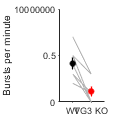

ylim([0 1]);
yticks([0:0.5:1]);
yticklabels({'0','0.5','10000000'})
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\MRSburstNum.eps',gcf);  

    
[h, p] = compare2P(WT_spikesPerBurst,MRS_spikesPerBurst,{'WT', 'VG3 KO'}, 'Spikes per burst', [1.5 2]);

    0.0208



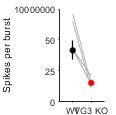

ylim([0 75]);
yticks([0:25:75]);
yticklabels({'0','25','50','10000000'})
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\MRSspikesPerBurst.eps',gcf);

    
[h, p] = compare2P(WT_burstDur/1000,MRS_burstDur/1000,{'WT', 'VG3 KO'}, 'Burst duration (s)', [1.5 2]);

    0.0937



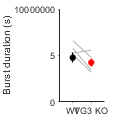

ylim([0 10]);
yticks([0:5:10]);
yticklabels({'0','5','10000000'})
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\MRSburstDuration.eps',gcf);


[h, p] = compare2P(WT_CVISI,MRS_CVISI,{'WT', 'VG3 KO'}, 'CVISI', [1.5 2]);

   2.8677e-04



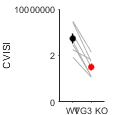

ylim([0 4]);
yticks([0:2:4]);
yticklabels({'0','2','10000000'})
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\MRSCVISIs.eps',gcf);

    
[h, p] = compare2P(WT_spikeCounts, MRS_spikeCounts,{'WT', 'VG3 KO'}, 'Spikes frequency (Hz)', [1.5 2]);

    0.3940



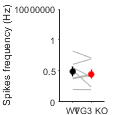

ylim([0 1.5])
yticks([0:0.5:1.5])
yticklabels({'0','0.5','1','10000000'})
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\MRSspikeFreq.eps',gcf);

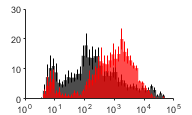


figure; 
histogram('BinCounts', mean(WT_binCounts,1), 'BinEdges', edges,'FaceAlpha',0.7,'EdgeColor','none', 'FaceColor','k'); hold on;
errorbar(edges2(1:end-1),mean(WT_binCounts,1),sterr(WT_binCounts,1),'LineStyle', 'none','Color','k','CapSize',0);
histogram('BinCounts', mean(MRS_binCounts,1), 'BinEdges', edges,'FaceAlpha',0.7,'EdgeColor','none','FaceColor','r');
errorbar(edges2(1:end-1),mean(MRS_binCounts,1),sterr(MRS_binCounts,1),'LineStyle', 'none','Color','r','CapSize',0);
set(gca,'XScale','log');
axis([10^0 10^5 -inf inf]);


xticks([10^0,10^1,10^2,10^3,10^4,10^5])
ylim([0 30]);
yticks([0:10:30]);
set(gca,'XminorTick','off')
xticklabels({'10^0','10^1','10^2','10^3','10^4','10^5'})
figQuality(gcf,gca,[2 1.2])
print('.\EPS Panels\MRS_ISIhisto.pdf','-dpdf')

%export_fig('.\EPS Panels\MRS_ISIhisto.eps',gcf);
    


%%WT versus P2ry1 KO analysis
burst_thr = 1000;
streakForBurst = 10;

%%WT traces
datadir = '.\Data\WT\'

datadir = '.\Data\WT\'

filelist = loadFileList([datadir '*.abf']);

%all spikes
for i = 1:size(filelist,1)
     [d,time] = loadPclampData(filelist{i});
    spikes = findSpikes(d, time*1000, [0 600], .3,0);
    bursts = findBursts(spikes.ISI, burst_thr, spikes.times, streakForBurst)

     [~,name,~] = fileparts(filelist{i});
     save([datadir name '_spikes.mat'],'spikes','bursts','-mat')
end

opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\WT\15719003.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1750.6 s ~ 29 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 534 MB


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 3
        burstsLocs: [3×2 double]
     spikePerBurst: [3×1 double]
         durations: [3×1 double]
          burstThr: 1000


opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\WT\15723000.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1677.6 s ~ 28 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 512 MB


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 7
        burstsLocs: [7×2 double]
     spikePerBurst: [7×1 double]
         durations: [7×1 double]
          burstThr: 1000


opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\WT\15723002.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1802.5 s ~ 30 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 550 MB


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 2
        burstsLocs: [2×2 double]
     spikePerBurst: [2×1 double]
         durations: [2×1 double]
          burstThr: 1000


opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\WT\15723003.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1884.5 s ~ 31 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 575 MB


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 5
        burstsLocs: [5×2 double]
     spikePerBurst: [5×1 double]
         durations: [5×1 double]
          burstThr: 1000


opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\WT\15723006.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 2010.4 s ~ 34 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 614 MB


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 3
        burstsLocs: [3×2 double]
     spikePerBurst: [3×1 double]
         durations: [3×1 double]
          burstThr: 1000


opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\WT\15724007.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1930.4 s ~ 32 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 589 MB


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 4
        burstsLocs: [4×2 double]
     spikePerBurst: [4×1 double]
         durations: [4×1 double]
          burstThr: 1000


opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\WT\15725007.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1808.8 s ~ 30 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 552 MB


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 5
        burstsLocs: [5×2 double]
     spikePerBurst: [5×1 double]
         durations: [5×1 double]
          burstThr: 1000


opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\WT\15822000.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1814.6 s ~ 30 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 554 MB


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 3
        burstsLocs: [3×2 double]
     spikePerBurst: [3×1 double]
         durations: [3×1 double]
          burstThr: 1000


opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\WT\15822002.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1898.1 s ~ 32 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 579 MB


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 4
        burstsLocs: [4×2 double]
     spikePerBurst: [4×1 double]
         durations: [4×1 double]
          burstThr: 1000


opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\WT\15822004.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1910.7 s ~ 32 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 583 MB


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 3
        burstsLocs: [3×2 double]
     spikePerBurst: [3×1 double]
         durations: [3×1 double]
          burstThr: 1000



%% KO Traces
datadir = '.\Data\P2ry1 KO\'

datadir = '.\Data\P2ry1 KO\'

filelist = loadFileList([datadir '*.abf']);

%all spikes
for i = 1:size(filelist,1)
     [d,time] = loadPclampData(filelist{i});
    spikes = findSpikes(d, time*1000, [0 600], .3,0);
    bursts = findBursts(spikes.ISI, burst_thr, spikes.times, streakForBurst)

     [~,name,~] = fileparts(filelist{i});
     save([datadir name '_spikes.mat'],'spikes','bursts','-mat')
end

opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO\15724000.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1832.2 s ~ 31 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 559 MB


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 1
        burstsLocs: [5.2554e+05 5.3356e+05]
     spikePerBurst: 24
         durations: 8.0141e+03
          burstThr: 1000


opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO\15724001.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1800.1 s ~ 30 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 549 MB


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 1
        burstsLocs: [2.4560e+04 2.7543e+04]
     spikePerBurst: 13
         durations: 2.9830e+03
          burstThr: 1000


opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO\15724002.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1801.2 s ~ 30 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 550 MB


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 0
        burstsLocs: [0×2 double]
     spikePerBurst: [0×1 double]
         durations: [0×1 double]
          burstThr: 1000


opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO\15724004.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1800.4 s ~ 30 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 549 MB


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 4
        burstsLocs: [4×2 double]
     spikePerBurst: [4×1 double]
         durations: [4×1 double]
          burstThr: 1000


opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO\15724005.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1896.5 s ~ 32 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 579 MB


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 3
        burstsLocs: [3×2 double]
     spikePerBurst: [3×1 double]
         durations: [3×1 double]
          burstThr: 1000


opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO\15725000.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1929.5 s ~ 32 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 589 MB


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 0
        burstsLocs: [0×2 double]
     spikePerBurst: [0×1 double]
         durations: [0×1 double]
          burstThr: 1000


opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO\15725005.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1225.8 s ~ 20 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 374 MB


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 0
        burstsLocs: [0×2 double]
     spikePerBurst: [0×1 double]
         durations: [0×1 double]
          burstThr: 1000


opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO\15725006.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1835.1 s ~ 31 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 560 MB


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 1
        burstsLocs: [5.0892e+05 5.1284e+05]
     spikePerBurst: 13
         durations: 3.9268e+03
          burstThr: 1000


opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO\15905000.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1801.1 s ~ 30 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 550 MB


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 0
        burstsLocs: [0×2 double]
     spikePerBurst: [0×1 double]
         durations: [0×1 double]
          burstThr: 1000


opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO\15905002.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1804.0 s ~ 30 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 551 MB


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 0
        burstsLocs: [0×2 double]
     spikePerBurst: [0×1 double]
         durations: [0×1 double]
          burstThr: 1000


opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - SGNs\Data\P2ry1 KO\15905004.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1845.5 s ~ 31 min
sampling interval: 25 µs
memory requirement for complete upload in matlab: 563 MB


bursts = struct with fields:
    streakForBurst: 10
         numBursts: 3
        burstsLocs: [3×2 double]
     spikePerBurst: [3×1 double]
         durations: [3×1 double]
          burstThr: 1000


%Control versus MRS analysis
edges = 10.^(-1:0.1:6);
edges2 = 1.13*10.^(-1:0.1:6);
midpoint = sqrt(edges(1:end-1).*edges(2:end));
test = [edges' edges2' [midpoint'; NaN]];

WT_SGN_data = loadFileList('.\Data\WT\*_spikes.mat');
WT_numBursts = []; WT_spikesPerBurst = []; WT_burstDur = []; WT_spikeCounts = []; WT_binCounts = [];
WT_CVISIs = [];
for i=1:size(WT_SGN_data)
    load(WT_SGN_data{i});
    h = histcounts(spikes.ISI, edges);
    WT_binCounts(i,:) = h;
    WT_numBursts(i,1) = bursts.numBursts; 
    WT_spikesPerBurst(i,1) = mean(bursts.spikePerBurst,1);
    WT_burstDur(i,1) =  mean(bursts.durations);
    WT_spikeCounts(i,1) = spikes.numSpikes/600;
    WT_CVISI(i,1) = std(spikes.ISI,[],1)/mean(spikes.ISI,1);
end

KO_SGN_data = loadFileList('.\Data\P2ry1 KO\*_spikes.mat');
KO_numBursts = []; KO_spikesPerBurst = []; KO_burstDur = []; KO_spikeCounts = []; KO_binCounts = [];
KO_CVISIs = [];
for i=1:size(KO_SGN_data)
    load(KO_SGN_data{i});
    h = histcounts(spikes.ISI, edges);
    KO_binCounts(i,:) = h;
    KO_numBursts(i,1) = bursts.numBursts; 
    KO_spikesPerBurst(i,1) = mean(bursts.spikePerBurst,1);
    KO_burstDur(i,1) =  mean(bursts.durations);
    KO_spikeCounts(i,1) = spikes.numSpikes/600;
    KO_CVISI(i,1) = std(spikes.ISI,[],1)/mean(spikes.ISI,1);
end



%%
dim = [0.5 1.2]

dim =     0.5000    1.2000


[h, p] = compare2(WT_numBursts/10,KO_numBursts/10,{'WT', 'P2y KO'}, 'Bursts per minute', [1.5 2]);

   4.2411e-04



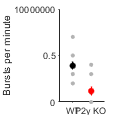

ylim([0 1]);
yticks([0:0.5:1]);
yticklabels({'0','0.5','10000000'})
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\WTKO_burstNum.eps',gcf);  

    
[h, p] = compare2(WT_spikesPerBurst,KO_spikesPerBurst,{'WT', 'P2y KO'}, 'APs per burst', [1.5 2]);

    0.0595



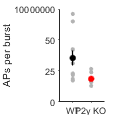

ylim([0 75]);
yticks([0:25:75]);
yticklabels({'0','25','50','10000000'})
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\WTKO_spikesPerBurst.eps',gcf);

    
[h, p] = compare2(WT_burstDur/1000,KO_burstDur/1000,{'WT', 'P2y KO'}, 'Burst duration (s)', [1.5 2]);

    0.7282



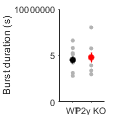

ylim([0 10]);
yticks([0:5:10]);
yticklabels({'0','5','10000000'})
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\WTKO_burstDuration.eps',gcf);


[h, p] = compare2(WT_CVISI,KO_CVISI,{'WT', 'P2y KO'}, 'CVISI', [1.5 2]);

    0.0023



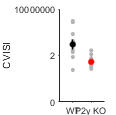

ylim([0 4]);
yticks([0:2:4]);
yticklabels({'0','2','10000000'})
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\WTKO_CVISIs.eps',gcf);

    
[h, p] = compare2(WT_spikeCounts, KO_spikeCounts,{'WT', 'P2y KO'}, 'AP frequency (Hz)', [1.5 2]);

    0.5248



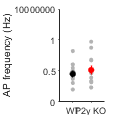

ylim([0 1.5])
yticks([0:0.5:1.5])
yticklabels({'0','0.5','1','10000000'})
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\WTKO_spikeFreq.eps',gcf);

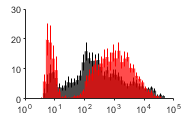


figure; 
histogram('BinCounts', mean(WT_binCounts,1), 'BinEdges', edges,'FaceAlpha',0.7,'EdgeColor','none', 'FaceColor','k'); hold on;
errorbar(edges2(1:end-1),mean(WT_binCounts,1),sterr(WT_binCounts,1),'LineStyle', 'none','Color','k','CapSize',0);
histogram('BinCounts', mean(KO_binCounts,1), 'BinEdges', edges,'FaceAlpha',0.7,'EdgeColor','none','FaceColor','r');
errorbar(edges2(1:end-1),mean(KO_binCounts,1),sterr(KO_binCounts,1),'LineStyle', 'none','Color','r','CapSize',0);
set(gca,'XScale','log');
axis([10^0 10^5 -inf inf]);


xticks([10^0,10^1,10^2,10^3,10^4,10^5])
ylim([0 30]);
yticks([0:10:30]);
set(gca,'XminorTick','off')
xticklabels({'10^0','10^1','10^2','10^3','10^4','10^5'})
figQuality(gcf,gca,[2 1.2])
print('.\EPS Panels\WTKO__ISIhisto.pdf','-dpdf')

%export_fig('.\EPS Panels\MRS_ISIhisto.eps',gcf);


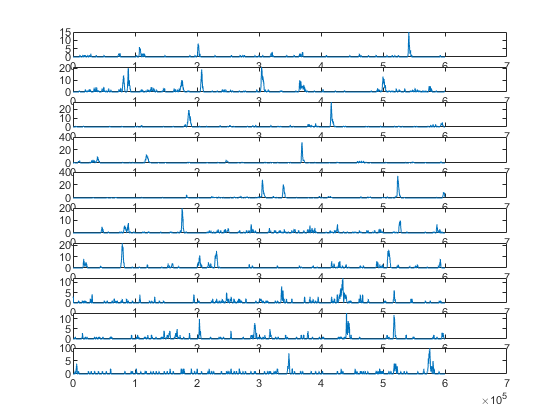

spike_paths = loadFileList('.\Data\WT\*spikes.mat');
ISIs = [];
convolved = [];
figure;
for i = 1:10
    load(spike_paths{i});
    newTimes = round(spikes.times);
    spikesBin = zeros(size(0:1:600000));
    spikesBin(newTimes) = 1;
    convData = conv(spikesBin',ones(1000,1),'same');
    convolved(i,:) = decimate(convData,1000);
    subplot(size(spike_paths,1),1,i)
        plot(conv(spikesBin',ones(1000,1),'same'))
    %subplot(size(WT_spike_paths,1),2,i);
   %     plot(spikes.ISI,'.'); set(gca, 'YScale', 'log'); ylim([10^0 10^5]);
   %  subplot(size(WT_spike_paths,1),2,i+size(WT_spike_paths,1));
    %    histogram(spikes.times*1000, 600/10); ylim([0 100]);
    ISIs = [ISIs; spikes.ISI];
end

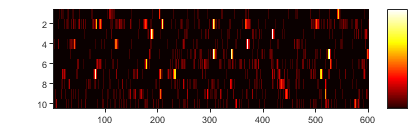


figure; imagesc(convolved); colormap htmp; caxis([0 20]);
colorbar;
figQuality(gcf,gca,[4.25 1.3]);
print(['.\EPS Panels\WT_heatmap.pdf'],'-dpdf')

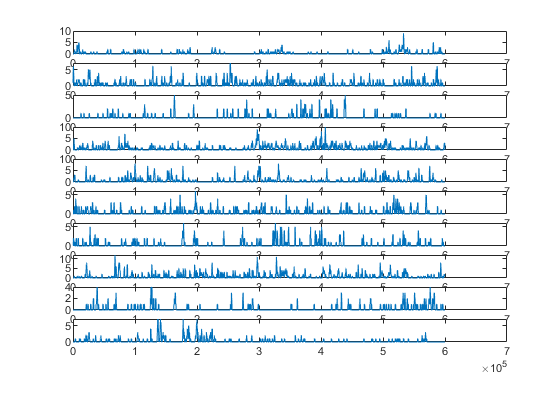

%KO 
spike_paths = loadFileList('.\Data\P2ry1 KO\*spikes.mat');
ISIs = [];
convolved = [];
figure;
for i = 1:10
    load(spike_paths{i});
    newTimes = round(spikes.times);
    spikesBin = zeros(size(0:1:600000));
    spikesBin(newTimes) = 1;
    convData = conv(spikesBin',ones(1000,1),'same');
    convolved(i,:) = decimate(convData,1000);
    subplot(size(spike_paths,1),1,i)
        plot(conv(spikesBin',ones(1000,1),'same'))
    %subplot(size(WT_spike_paths,1),2,i);
   %     plot(spikes.ISI,'.'); set(gca, 'YScale', 'log'); ylim([10^0 10^5]);
   %  subplot(size(WT_spike_paths,1),2,i+size(WT_spike_paths,1));
    %    histogram(spikes.times*1000, 600/10); ylim([0 100]);
    ISIs = [ISIs; spikes.ISI];
end

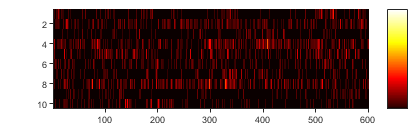


figure; imagesc(convolved); colormap htmp; caxis([0 20]);
colorbar;
figQuality(gcf,gca,[4.25 1.3]);
print(['.\EPS Panels\KO_heatmap.pdf'],'-dpdf')